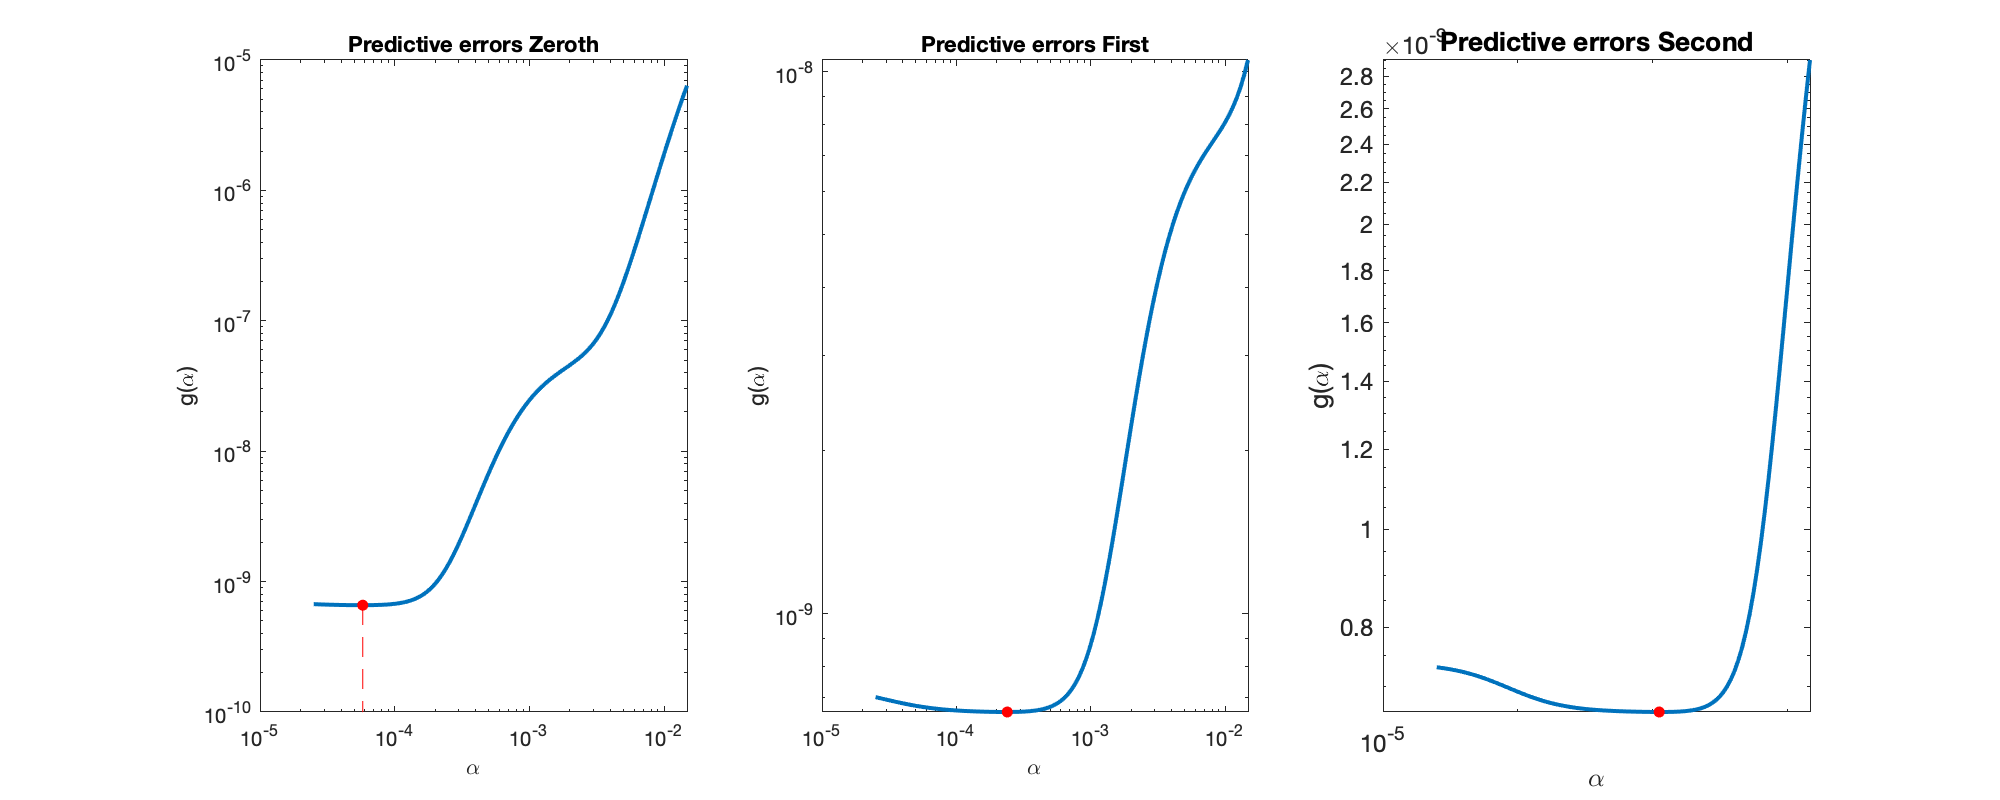

clear
clc
clear

data = load('ifk.mat');
%addpath('/Users/mathuser/Documents/PHD/Spring_2022/Inverse Theory/regu')

d = data.d;
sigma = 5e-5;

m = size(d,1);
dx = 1/m;

% Form the grid points x and y
J = 1:20;
[x, y] = deal((J-1/2)*dx);

% m function

m_fun = @(alpha,G,d,L) (G'*G + alpha^2*(L'*L))\(G'*d);

% Form G matrix
G = dx*x.*exp(-x.*y');

% The zeroth order Tikhonov regularization

L0 = eye(20);

% The first order Tikhonov regularization

D1 = diag(ones(m-1,1),1);
L1 = -eye(m-1,m) + D1(1:m-1,:);

% The second order Tikhonov regularization

D2 = -2*diag(ones(m-1,1),1) + diag(ones(m-2,1),2);
L2 = eye(m-2,m) + D2(1:m-2,:);

% alpha min and max
alpha_min = 2.5058e-5;
alpha_max = 0.0148;

% form the array of alpha
nt = 100;
NJ = (nt-(1:nt))/(nt-1);
alpha = alpha_min*(alpha_max/alpha_min).^NJ;

yg = zeros(nt,1);
alpha_optimal = zeros(3,1);

for j = 1:3
    
    if(j == 1)
        L = L0; order = 'Zeroth';
    elseif(j == 2)
        L = L1; order = 'First';
    else
        L = L2; order = 'Second';
    end
    
    for i = 1:nt
        yg(i) = g(alpha(i),G,L,d,m);
    end
    
    [ming,id] = min(yg);
    
    alpha_optimal(j) = alpha(id);
    
    subplot(1,3,j)
    
    loglog(alpha,yg,'LineWidth',2)
    
    ax=axis; hold on
    H=loglog(alpha_optimal(j),ming,'.r',[alpha_optimal(j),alpha_optimal(j)],[ming/nt,ming],'--r');
    set(H,'markersize',15);
    hold off
    axis(ax)
    xlabel('\alpha');
    ylabel('g(\alpha)'); 
    title(sprintf('Predictive errors {%s}', order));
    
end

h_gc = gca;
h_gc.FontSize = 12;
set(gcf,'Position',[550 550 1000 400])

I chose $\alpha_{min}$ eqaul to the value of $\alpha$ obtained from the zeroth order Tikhonov and $\alpha_{max}$ equal to the value of $\alpha$ obtained from second order Tikhonov in previous activities.

To chose an optimal value of $\alpha$, we look at value of $\alpha$ where the function $g(\alpha)$ reach its minimum value. By doing that we obtain the following value

fprintf('for the zeroth order Tikhonov regularization \alpha = %.4e',alpha_optimal(1))

for the zeroth order Tikhonov regularization lpha = 5.7924e-05

fprintf('for the first order Tikhonov regularization \alpha = %.4e',alpha_optimal(2))

for the first order Tikhonov regularization lpha = 2.3917e-04

fprintf('for the second order Tikhonov regularization \alpha = %.4e',alpha_optimal(3))

for the second order Tikhonov regularization lpha = 1.1234e-03

function ga = g(alpha,G,L,d,m)

    GH = (G'*G + alpha^2*(L'*L))\G';
    m_a = GH*d;
    ga = m*norm(G*m_a-d)^2/trace(eye(m)-G*GH)^2;
end
